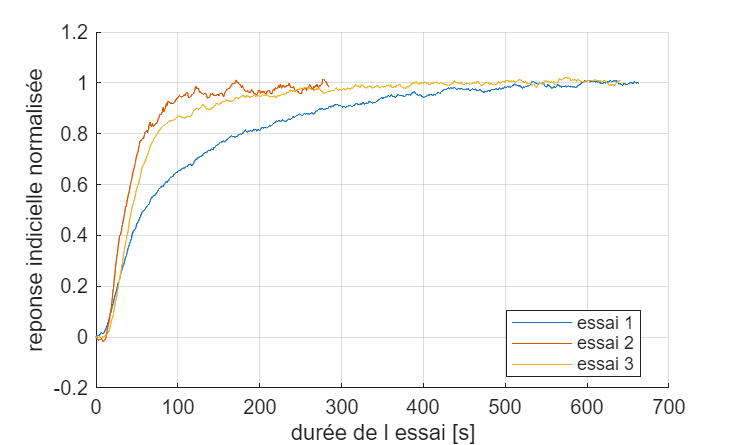

%avec boucle

ysp=A(:,1);
a=diff(ysp);
ydif=a(a~=0);
xdif=find(a~=0);
clf; hold on; grid on

N = 2;   % A CHANGERRRR nombre d'essais FAUT CHANGER ICI SI CA DIT Index exceeds the number of array elements
for k = 1:N
    bi = xdif(k);      
    bf = xdif(k+1);    
    
    idx = bi:bf;
    yk = y(idx);

   
    y0 = yk(1);
    yk = yk - y0;

    % normalisation
    yinf = mean(yk(max(1,end-10):end));   % moyenne des 10 derniers points
    yk = yk / yinf;

    t0 = idx - bi;
    plot(t0, yk);
end

% ---- DERNIER ESSAI : de xdif(end) jusqu'à la fin ----
bi = xdif(end);
bf = length(y);           % ou bf = length(t) si t existe et même taille

idx = bi:bf;
yk = y(idx);

y0 = yk(1);
yk = yk - y0;

yinf = mean(yk(max(1,end-10):end));
yk = yk / yinf;

t0 = idx - bi;
plot(t0, yk);


legend(compose("essai %d", 1:(N+1)), 'Location','best')
xlabel('durée de l essai [s]')
ylabel('reponse indicielle normalisée')

%Lancer simulink ,LAISSER ATTEINDRE LE REGIME EPRMANENT
%  faire ton scope , stoper la simulation, cliquer sur mise
%en forme indent
%remplacer le N par nombre echelon - 1 et lancer le code 